clear, close all, clc


Problem 1:

bird = 48;
peop = 52;

Neural Network Parameters

nn_bird = 45;
nn_peop = 57;

nn_badbird = 3;
nn_badpeop = 5;


NA Parameters

na_bird = 47;
na_peop = 42;

na_badbird = 1;
na_badpeop = 11;


1a. The neural network made 8 mistakes where the NA made 11. Therfore the NN made fewer mistakes.

1b. Since we care very much about misidentifying a bird but not so much about misidentifying a person. We will assume there is someway for the human to manually overide the door in the event the detector is failing to let them out. This allows for us to only look at the precentage correct for birds.

nn_bird_correct = 1-3/48

nn_bird_correct = 0.9375

nn_peop_correct = 1-5/52

nn_peop_correct = 0.9038


na_bird_correct = 1-1/48

na_bird_correct = 0.9792

na_peop_correct = 1-11/52

na_peop_correct = 0.7885

Since the NN only gets a 93.75% correct for bird identifications and NA gets 97.92% correct for bird identifacations, the NA is better for the Zoo.

1c.

new_birds = 99;
new_peop = 1;

new_na_bird = na_bird_correct*new_birds

new_na_bird = 96.9375

new_na_peop = na_peop_correct*new_peop

new_na_peop = 0.7885


new_nn_bird = nn_bird_correct*new_birds

new_nn_bird = 92.8125

new_nn_peop = nn_peop_correct*new_peop

new_nn_peop = 0.9038

We'll use the convention if more then 70% of the animal was "detected as the corresponding animal" correctly, we will consider that a positive detection. The new tables will be

NA Bird        97    2

NA Person   1      0 

NN Bird        93    6

NN Person   1      0 

2a. The pdf of the sum of two identical exponential functions.

Lets start by defining the PDF of an exponential function


$$PDF(x) = \lambda e^{\lambda x}$$


Lets now take the convolution of the PDF of two identical distributions and see the result


$$PDF(x) = \int_{0}^{z}\lambda_{1}e^{-\lambda x_{1}}\lambda_{2} e^{\lambda_{2}(z-x)}\,dx$$


Since the distributions are identical $\lambda_1 =\lambda_2$ we can combine the exponents


$$PDF(x)=\int_{0}^{z}\lambda^{2}e^{-\lambda z}\,dx$$


Now we can pull out all the tersm as they are no longer dependent on x


$$PDF(x) =\lambda^{2}e^{-\lambda z}\int_{0}^{z}\,dx$$


Now the integral is trivial


$$PDF(x)=\lambda^{2}e^{-\lambda z}z$$


2b. Assuming that a zero-mean unity variance gaussian distribution means a $\mu =0\;$and $\sigma =1\;$

then 


$$PDF(x)=\frac{1}{\sigma\sqrt{2\pi}}e^{-\frac{1}{2}\left(\frac{x-\mu}{\sigma}\right)^{2}}}$$


Substituing in the values for $\sigma$ and $\mu$


$$PDF(x)=\frac{1}{\sqrt{2\pi}}e^{-\frac{1}{2}\left(x\right)^{2}}}$$


Dividing it by itself obviously returns 1


$$PDF(x)=\frac{\frac{1}{\sqrt{2\pi}}e^{-\frac{1}{2}\left(x\right)^{2}}}{\frac{1}{\sqrt{2\pi}}e^{-\frac{1}{2}\left(x\right)^{2}}}=1}$$


2c.

To create the 2D gaussian distribution I created two 1D gaussian distribtions. I then iterated through each set of two values in the two distributions and took the magnitude.

To start we will use the formula for a 2D gaussian distribution


$$PDF(x,y)=\frac{1}{2\pi\sigma^{2}}e^{-\frac{x^{2}+y^{2}}{2\sigma^{2}}}$$


This will output a vector of length 2, $X\hat{i}+Y\hat{j}$

We then want the magnitude of the vector so we will use 


$$mag = \sqrt {X^{2}\hat{i}+Y^{2}\hat{j}}$$


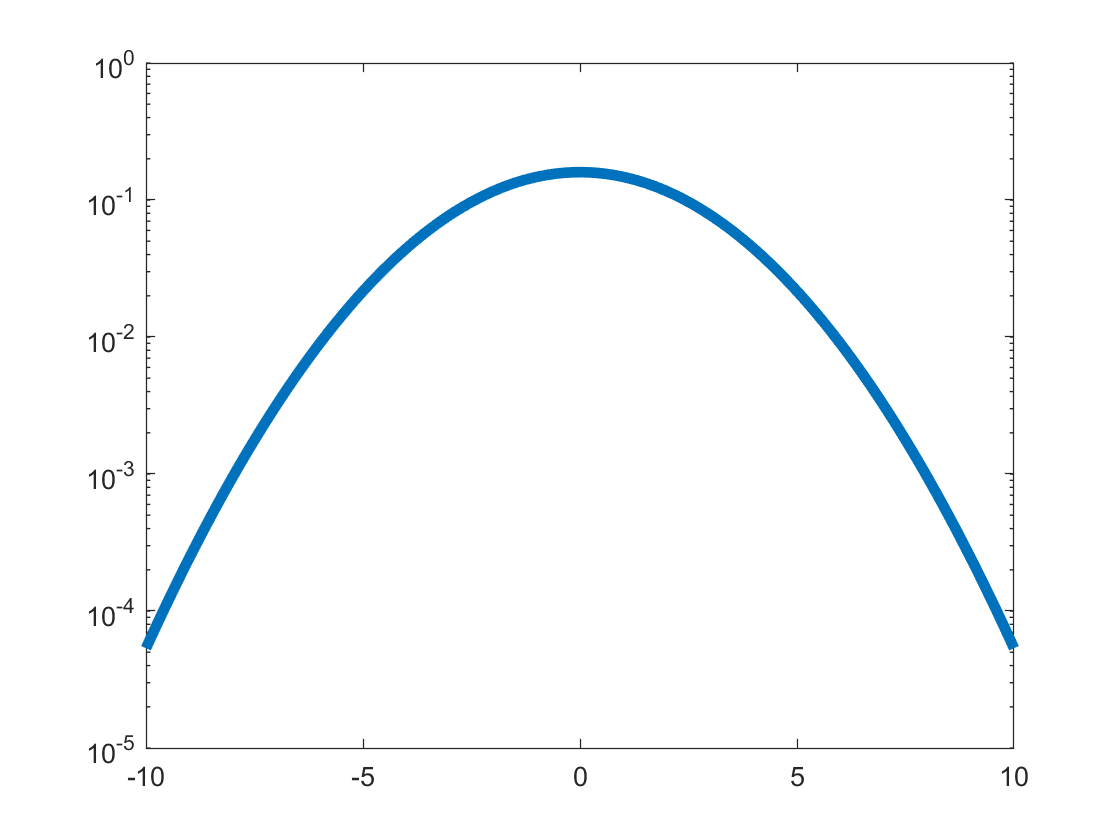

x = linspace(-10,10,1000);
sig = 2.5;
mu = 0;
gaus1 = makedist("Normal",mu,sig);
semilogy(x,pdf(gaus1,x),"LineWidth",4);


x = linspace(-10,10,1000);
sig = 2.5;
mu = 0;
gaus2 = makedist("Normal",mu,sig);
semilogy(x,pdf(gaus2,x),"LineWidth",4);

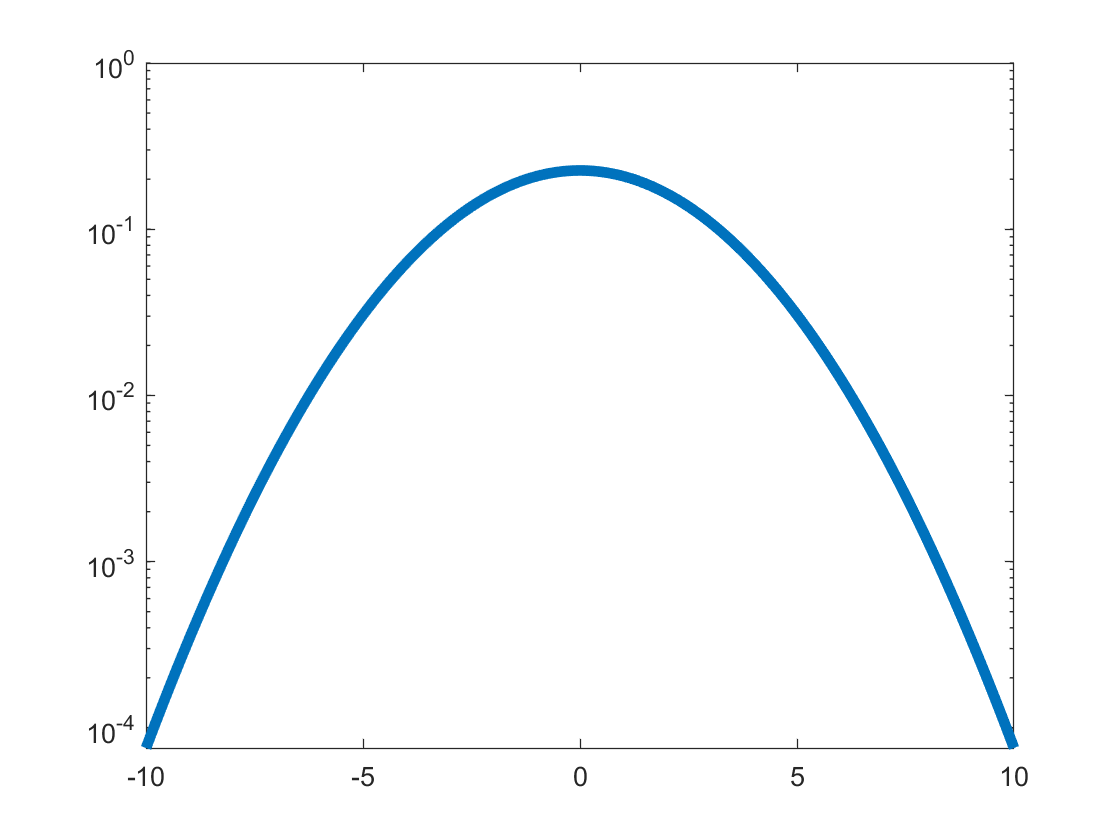


x_vals = pdf(gaus1,x);
y_vals = pdf(gaus2,x);

gaus_2d = zeros(2,length(x_vals));
mag = zeros(length(x_vals));
for k = 1:length(x_vals)
    gaus_2d(k,1) = x_vals(k);
    gaus_2d(k,2) = y_vals(k);
    mag(k) = sqrt(gaus_2d(k,1)^2+gaus_2d(k,2)^2);
end
semilogy(x,mag,'Linewidth',4)